# Walkthrough - Simulink Example

This live script exercises a Simulink model implemented using the workflow described in the [Guy on Simulink](https://blogs.mathworks.com/simulink/) blog series [Unifying MATLAB and Simulink: A User Story](https://blogs.mathworks.com/simulink/2022/04/22/unifying-matlab-and-simulink-a-user-story-part-1).

## Initial Setup

Let's beign with specyfing the model:

clear
mdl = 'vehicle_SL';
open_system(mdl)

## Simulating one configuration

Let's try a first simulation. the model uses an variable `vehicleObject` that can be created from one ot the classes in the `vehicle` package.

vehicleObject = vehicle.sportSedan;

With this setup, the vehicle is configured to simulate 3 degrees freedom (vertical translation, roll, pitch)

vehicleObject.Suspension

ans = slPart suspension.threeDof
Instantiated in: --- unset ---
     FrontLeft: [1×1 suspension.springDamperLinear]
    FrontRight: [1×1 suspension.springDamperLinear]
      RearLeft: [1×1 suspension.springDamperLinear]
     RearRight: [1×1 suspension.springDamperLinear]

No logged data


We can simulate the model and see the results

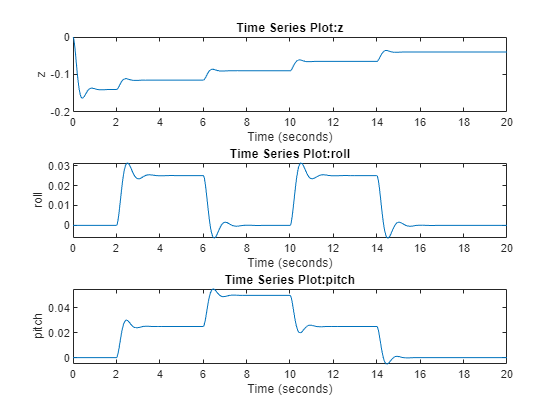

out = sim(mdl);
vehicleObject.getLog(out);
vehicleObject.plotCG();

## Simulating a second configuration

You can repeat the same process with other classes in the `vehicle` package. I **strongly** recommend leveraging tab-completion to discover exesting class, properties and methods. For example:

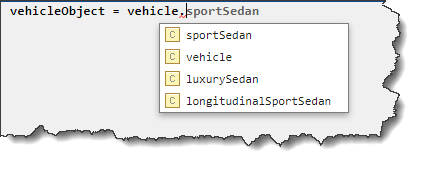

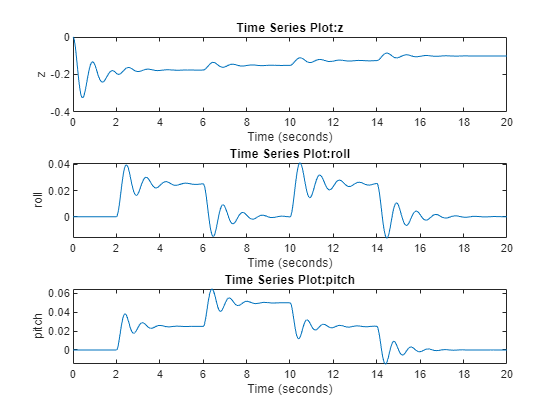

vehicleObject = vehicle.luxurySedan;
out = sim(mdl);
vehicleObject.getLog(out);
vehicleObject.plotCG();

Following the examples in the vehicle package, you can create as many pre-defined configurations as desired

## Swapping Part

The previous configurations are using a 2 DoF configuration. For simpler tests, the model can be configured to use suspensions with different degrees of freedom

vehicleObject = vehicle.sportSedan;
vehicleObject.Suspension = suspension.twoDofLateral;

You can observe that the model now contains only two spring-damper systems:

vehicleObject.Suspension

ans = slPart suspension.twoDofLateral
Instantiated in: --- unset ---
     Left: [1×1 suspension.springDamperLinear]
    Right: [1×1 suspension.springDamperLinear]

No logged data


When simulating, theree is only motion in the Z and Roll degrees of freedom:

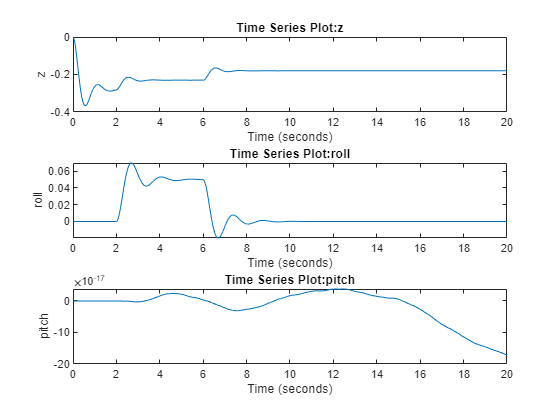

out = sim(mdl);
vehicleObject.getLog(out);
vehicleObject.plotCG();

## Tuning Numerical values

In addition to swapping parts, it is possible to tune individual numerical parameters. For example, we can try increasing the weight of the vehicle to see the impact on the motion. Let's use the 1 degree of freedom suspension for simplicity

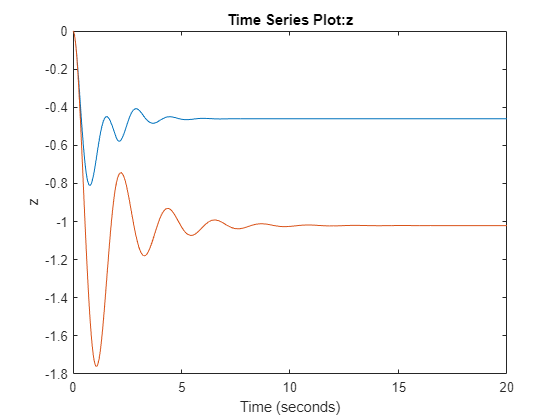

vehicleObject = vehicle.sportSedan;
vehicleObject.Suspension = suspension.oneDof;
out = sim(mdl);
vehicleObject.getLog(out);
figure
vehicleObject.plotZ();
vehicleObject.Body.Mb = 2* vehicleObject.Body.Mb;
out = sim(mdl);
vehicleObject.getLog(out);
hold on
vehicleObject.plotZ();

## System Configurator App

With a single object configuring the entire model, it becomes straightforward to create an App to interact with the object interactively. Click [this link](matlab:vehicleObject = vehicle.sportSedan; systemConfigurator(mdl);) to execute the following code to try the app:

Here is a visual help for the app:

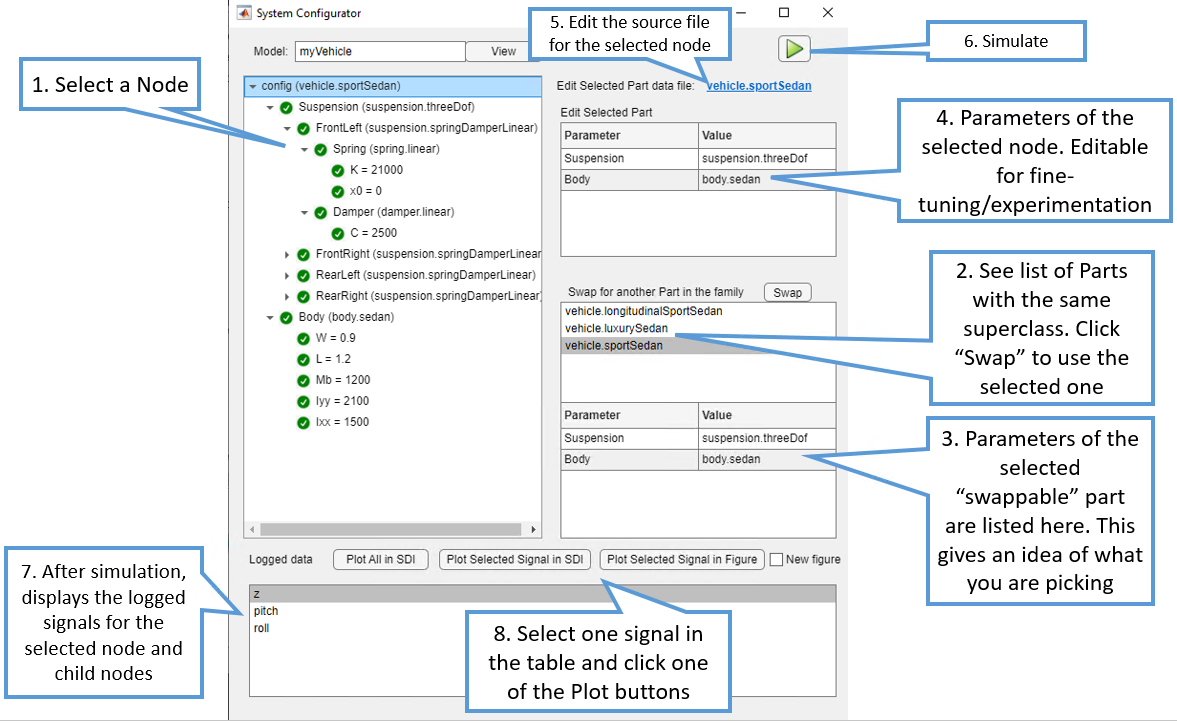

Copyright 2022 The MathWorks, Inc.